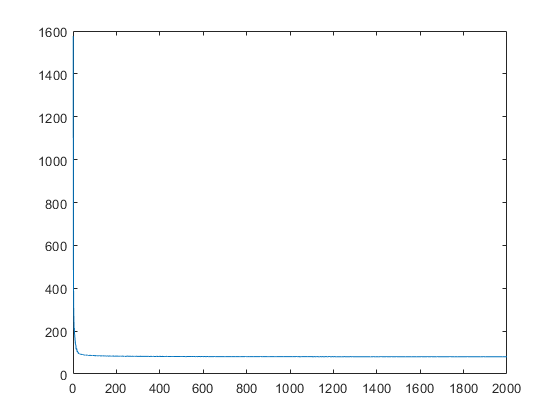

%max_epoch = 2;

%%%%%%%%%%%%%%%%%%%%%%%%%%input para%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%n = 362;
%k = 2;
%d = 1984;
%datasetLbl = trLb;
%datasetD = trD;
%w = zeros(d,k);
%keySet = [-1 1];
%valSet = [1 2];
%mapper = containers.Map(keySet, valSet);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%tuning para%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%eta0 = 1;
%eta1 = 100;
%C = 10;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%get value

%mapper(-1);
%i=2;
%yi = trLb(i);
%indx_yi = mapper(yi);
%w(:,1:0);
%w(:,[1:end]);
%w_yi = w(:,indx_yi);
%w_yi = w(:,[1:yi,yi_hat+1:end]);
%w_yi = w(:,indx_yi);
%-1*Inf(3,4)
%Inf(3,4);
%w_tmp = w;
%w_tmp(:,yi) = -1*Inf;


lossArr = [];
%indexArr = [];
for epoch = 1:max_epoch
    eta = eta0/(eta1+epoch);
    indices = randperm(n);
    loss = 0;
    for i = 1:n    
        %find indx_yi
        yi = datasetLbl(indices(i));%trLb(indices(i));
        xi = datasetD(:,indices(i));%trD(:,indices(i));
        indx_yi = mapper(yi);
        %find value_yi to update
        %value_yi = w(indx_yi);
        %find yi_hat
        w_tmp = w;
        w_tmp(:,indx_yi) = -1.*Inf;
        %size(w_tmp.');
        %size(xi);
        %find value_yi_hat to update
        [max_val, indx_yi_hat] = max((w_tmp')*xi);        
        %indx_yi_hat = indx_yi_hat;
        %size(w(:,indx_yi_hat));
        %size(xi);
        
        L = max(((w(:,indx_yi_hat)')*xi - (w(:,indx_yi)')*xi)+1,0);                        
        %find derivative
        if(L > 0)            
            diff_wyi = (w(:,indx_yi)./n) - ((xi).*C);
            diff_wyi_hat = (w(:,indx_yi_hat)./n) + ((xi).*C);
        else
            diff_wyi = (w(:,indx_yi)./n);
            diff_wyi_hat = (w(:,indx_yi_hat)./n);
        end
        
        %w_new = zeros(d,k);

        %update w with yi
        %w_new(:,indx_yi) = w(:,indx_yi) - (eta.*diff_wyi);

        %update w with yi_hat
        %w_new(:,indx_yi_hat) = w(:,indx_yi_hat) - (eta.*diff_wyi_hat);

        %update w with others
        for j=1:k
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %L = max(((w(:,indx_yi_hat)')*xi - (w(:,indx_yi)')*xi)+1,0);
            %if(L > 0)            
            %    diff_wyi = (w(:,indx_yi)./n) - ((xi).*C);
            %    diff_wyi_hat = (w(:,indx_yi_hat)./n) + ((xi).*C);
            %else
            %    diff_wyi = (w(:,indx_yi)./n);
            %    diff_wyi_hat = (w(:,indx_yi_hat)./n);
            %end
            %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            if(j == indx_yi)
                w(:,indx_yi) = w(:,indx_yi) - (eta.*diff_wyi);
            elseif(j == indx_yi_hat)
                w(:,indx_yi_hat) = w(:,indx_yi_hat) - (eta.*diff_wyi_hat);
            else                         
                diffOther = w(:,j)./n;
                w(:,j) = w(:,j) - (eta.*diffOther);
            end                                  
        end 
        %w = w_new;                        
        L = max(((w(:,indx_yi_hat)')*xi - (w(:,indx_yi)')*xi) + 1,0);        
        %w.^2
        %dg = diag(w*(w.'));
        
        tmp = (sum(vecnorm(w).^2)/(2*n));
        loss = loss + tmp + C*L;        
    end    
    lossArr = [lossArr loss];
    %indexArr = [indexArr epoch];
    %loss = 0;
end

wFinal = w;
plot(lossArr);